**SARAH AKTARI (part 2 - steady state variables)**

**Equations for the steady state of each gating variable over a range of voltage **

this portion of the code shows the steady state of each gating variable as the membrane potential increases and decreases. this helps to better understand the relationship between Na+, K+ and A-type current during and action potential. since this portion of the code uses a given range for voltage as opposed to being dependent on a differental equation and time, this portion is separate. the end goal of this portion was to visual each gating variable of Na+, K+, and A-type channels in its steady state in relation to each other. 

clearvars 
% 
Vm = (-100:1:20); %voltage vector in mV
%     % m variable 
alpha_m = (0.38.*(Vm+29.7))./(1-exp(-0.1.*(Vm+29.7)));
beta_m = 15.2.*exp(-0.0556.*(Vm+54.7));
% 
tau_m = 1./(alpha_m+beta_m);
m_inf = alpha_m./(alpha_m+beta_m);
% 
%     % h variable 
alpha_h = 0.266.*exp(-0.05.*(Vm+48));
beta_h = 3.8./(1+exp(-0.1.*(Vm+18)));
% 
tau_h = 1./(alpha_h+beta_h);
h_inf = alpha_h./(alpha_h+beta_h);
% 
%     % n variable 
alpha_n = (0.02.*(Vm+45.7))./(1-exp(-0.1.*(Vm+45.7)));
beta_n = 0.25.*exp(-0.0125.*(Vm+55.7));
% 
tau_n = 1./(alpha_n+beta_n);
n_inf = alpha_n./(alpha_n+beta_n);
% 
%     % a variable 
a_infpre = ((0.0761.*exp(0.0314.*(Vm)))./(1+exp(0.0346.*(Vm+1.17)))).^(1/3); % pre raising to exponential power 
a_inf = a_infpre .^ (1/3); % raised to 1/3 power 
tau_a = 0.3632 + (1.158./(1+exp(0.0497.*(Vm+55.96))));
% 
%     % b variable 
b_infpre = (1./(1+exp(0.0497.*(Vm+53.3)))); % pre raising to exponential power
b_inf = b_infpre .^ 4; % raising to power of 4, must create separate line
tau_b = 1.24 + (2.678./(1+exp(0.0624.*(Vm+50))));
% 
m_infinity = zeros(size(Vm)); %vector for m steady state variable 
% 
for v = 1:length(Vm) %value of m changes for each voltage
m_infinity(v) = alpha_m(v) / (alpha_m(v) + beta_m(v));
end
% 
h_infinity = zeros(size(Vm)); %vector for h steady state variable 
% 
for v = 1:length(Vm) %value of h changes for each voltage
h_infinity(v) = alpha_h(v) / (alpha_h(v) + beta_h(v));
end
% 
n_infinity = zeros(size(Vm)); %vector for n steady state variable
% 
for v = 1:length(Vm) %value of n changes for each voltage
n_infinity(v) = alpha_n(v) / (alpha_n(v) + beta_n(v));
end
% 

**Plots of gating variables over a range of voltage **

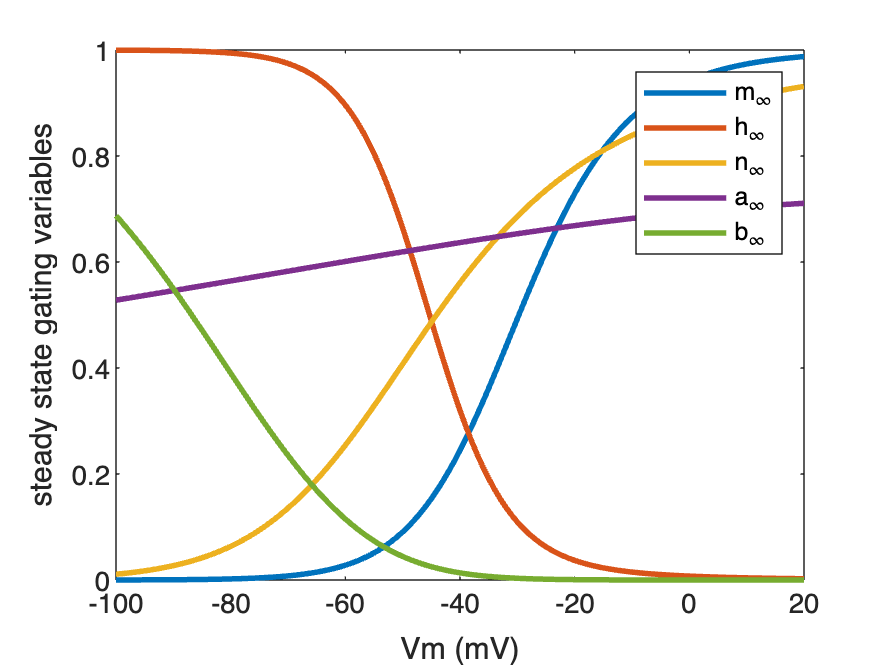

% % plotting steady state gating variables 
% 

plot(Vm, m_inf, 'LineWidth',2);
hold on 
plot(Vm,h_inf,'LineWidth', 2);
hold on 
plot(Vm, n_inf,'LineWidth', 2);
hold on 
plot(Vm, a_inf,'LineWidth', 2);
hold on 
plot(Vm, b_inf,'LineWidth', 2);
% 
legend ('m_{\infty}', 'h_{\infty}', 'n_{\infty}', 'a_{\infty}', 'b_{\infty}')
xlabel ('Vm (mV)')
ylabel ('steady state gating variables')